# 1-D Solar Cell Simulation Using Finite Element Method (Single Layer)

In this program, we simulate a perovskite solar cell's light absorbing layer (PAL), out of the three (ETL, PAL, HTL) that comprise a perovskite solar cell.

General Flow of the Program:

- Declaring Material Parameters

- Creating Space, Time, and Stimulus

- Finite Element Based Setting up System Matrices

- Defining the System of Drift-Diffusion Model Equations and Solving it

- Post Processing

## 1. Declaring Material Properties

The paramters list has been taken from the open source project, 

% Physical constants
eps0  = 8.8541e-12; % permittivity of free space (Fm-1)
q     = 1.6021e-19; % charge on a proton (C)
Fph   = 1.4e21;     % incident photon flux (m-2s-1)
kB    = 8.6173e-5;  % Boltzmann constant (eVK-1)

% Perovskite Layer General Parameters
T     = 298;       % temperature (K)
b     = 400e-9;    % perovskite layer width (m)
epsp  = 24.1*eps0; % permittivity of perovskite (Fm-1)

Beer-Lambert Model of light absorption is used to model light here, hence a single parameter alpha is enough.

alpha = 1.3e7;     % perovskite absorption coefficient (m-1)

Semiconductor parameters of the perovskite are now declared.

Ec    = -3.7;      % conduction band minimum (eV)
Ev    = -5.4;      % valence band maximum (eV)
Dn    = 1.7e-4;    % perovskite electron diffusion coefficient (m2s-1)
Dp    = 1.7e-4;    % perovskite hole diffusion coefficient (m2s-1)
gc    = 8.1e24;    % conduction band density of states (m-3)
gv    = 5.8e24;    % valence band density of states (m-3)
VT    = kB*T;      % thermal voltage (V)
Eg    = Ec-Ev;     % bandgap (eV)

% Ion parameters in perovskite
N0    = 1.6e25;        % typical density of ion vacancies (m-3)

Diffusion in the material of solar cell is modelled by the diffusivity relation based on Arrhenius Equation.

D     = @(Dinf, EA) Dinf*exp(-EA/(kB*T)); % diffusivity relation
DIinf = 6.5e-8;        % vacancy diffusion coefficient (m2s-1)
EAI   = 0.58;          % iodide vacancy activation energy (eV)
DI    = D(DIinf, EAI); % diffusion coefficient for iodide ions (m2s-1)

Normalising Factors - Essential to avoid memory overflow or singularity of matrices.

% These will be divded by appropriate parameters/variables.
ni      = sqrt(gc*gv)*exp(-Eg/(2*VT)); % intrinsic carrier density (m-3)
G0      = (Fph./b).*(1-exp(-alpha*b)); % typical rate of photogeneration (m-3s-1)
Tion = b/DI*sqrt(VT*epsp/(q*N0));  % characteristic ionic timescale (s)
VT = kB*T; % thermal voltage (V)
D0    = 11.896e-4; % Carrier Diffusion Normalising Constant (m2s-1)

Recombination in semiconductor can be of two types - Interfacial and Bulk, However, since only one layer is considered, we will have to model only bulk recombination.

% Bulk recombination parameters
beta = 1e-15;   % bimolecular recombination rate (m3s-1)
Augn = 0;       % electron-dominated Auger recombination rate (m6s-1) should be less than 1e-36
Augp = 0;       % hole-dominated Auger recombination rate (m6s-1)
n0   = gc*exp((Ec)/VT);  % typical electron density in perovskite (m-3)
p0   = gv*exp((Ev)/VT);  % typical hole density in perovskite (m-3)
ni2  = ni^2/(n0*p0);  % non-dim. n_i^2
Cn   = Augn*n0^2*p0/G0; % Auger recombination coefficient
Cp   = Augp*n0*p0^2/G0; % Auger recombination coefficient

## 2. Creating Space, Time, and Stimulus from Environment

% Grid Size
N = 400; % N is the number of subintervals, N+1 is the number of grid points
Ts = 15; %Total Simulation Time (s)

Initialising unknowns (aka boundary condition in time) - the main variables in the drift - diffusion model.

% Initialised with normalisation (values will be multiplied in the end with the 
% appropriate factors)
n = ones(N+1,1);
p = 0.9*ones(N+1,1); % assuming holes are 90% as many as electrons to negin
phi = zeros(N+1,1);

Mesh Generation for 1D is very simple (in first order) - especially if the space and time are divided linearly. For 2D and 3D the most basic shapes are triangles and tetrahedrons - they get very complex very quickly. Higher order elements are even more complex.

% Simply creating linear discretisation using linspace
x = linspace(0,b,N+1); %Array of elements between 0 and b equally spaced, creating N+1 total points
x = x/b; dx = x(2) - x(1); x = x'; % Normalising space and finding 'dx' for differenciation
t = linspace(0,Ts,600); % Will normalise time after creating applied voltage profile

This simulation assumes cell layer is present in lab conditions. Hence the following stimulus.

Stimulus - Light

% Considering constant light intensity throughout 15 seconds - again,
% normalising factors multiplied if needed
L = 1;

Stimulus - Applied Voltage Profile

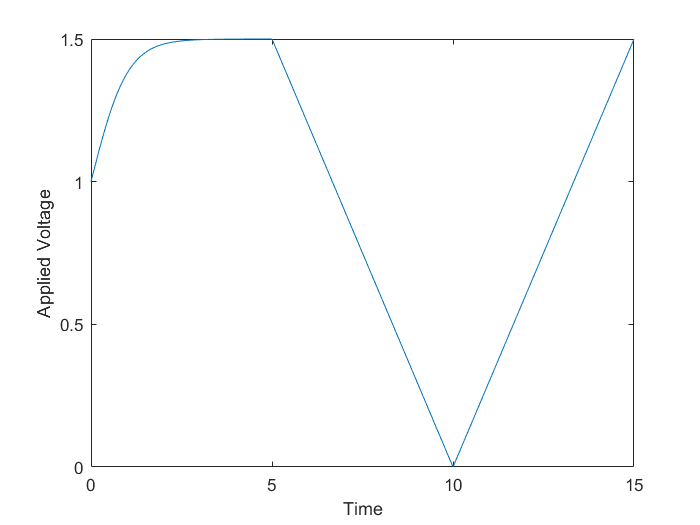

% Need to apply voltage since even after excitation from light, the
% movements of charge carriers will be random based on diffusion and bulk recombination.
% To obtain current, must define a voltage to make charges move.

% voltage changes from Vbi to 1 V (0-5 seconds - first 200 values in time) to 0 V (5-10 s, 200:400 values in time)
% and back again to 1.5 V (400:600, or 10-15 s)
v1 = (1.5-1)*tanh(t(1:200))+1; %ensures that parameters reach steady state
v2 = ((0-1.5)*(t(201:400)-5)/(10-5)) + 1.5; %v2 and v3 ensure that we consider all kinds of movement
v3 = ((1.5-0)*(t(401:600)-10)/(10-5));
V  = [v1 v2 v3];
figure; plot(t,V); xlabel("Time"); ylabel("Applied Voltage");


t = t/Tion; dt = t(2) - t(1); % Normalising time now, after ensuring correct voltage profile is set

How the stimulation affects semiconductor is governed by generation rate, it acts as the source term for drift diffusion model. It is based on Beer-Lambert model of light absorption.

% Generation Rate
G = (L*alpha*b/(1-exp(-alpha*b))*exp(-alpha*b*x));
G = G/G0; % Normalising

Defining recombination rates here, based on the parameters declared above.

% Bimolecular Recombination Rate
brate = beta*n0*p0/G0;
% Auger recombination rate
Auger = @(n,p,Cn,Cp,ni2) (Cn*n+Cp*p).*(n.*p-ni2);
% Total bulk recombination rate - Bimolecular + Auger
R = @(n,p) brate*(n.*p-ni2) + Auger(n,p,Cn,Cp,ni2)/G0;

## 3. Finite Element Method - Setting up System Matrices

Defining system matrices here that store values for both space and time. Originally declared unknowns matrices only accounts for space variations.

% 600 is the size of time matrix
phixt = zeros(N+1,600);
nxt = zeros(N+1,600);
pxt = zeros(N+1,600);
Jnxt = zeros(N+1,600);

#### Galerkin's Formulation - Describes how to setup FEM

Evaluate the following steps for local nodes:

Step 1: Create A Weighted Residual, or a 'weak' form of system.

Step 2: Substitute the unknowns with descretised unknowns matrices, then discretise the entire equation (aka apply weights to the residual form of system). The approximation takes place using basis functions - for 1D FEM, these are usually Lagrange Polynomials.

Step 3: Evaluate the integral of the now discretised weighted residual system across space equal to zero. Since we know the limits of integration, the evaluation gives values that can be defined in the form of matrices. This is the core of Galerkin's method.

Now, repeat the same steps for all nodes. Assemble the matrices for all nodes together - this gives us integrals of three forms - S (stiffness matrix), T (mass matrix) and Q. Their forms are given by:

% Setting up Global S, T and F Matrices Based on Galerkin's Formulation -
% This process can be automated directly from the math (from step 1) if
% better programming capability, but for now, these are good enough.

S = gallery('tridiag',N+1); 
% gallery creates test matrices of the form given in first argument.
% default tridiagonal matrix in MATLAB has the form [1 2 1] across the
% subdiagonal, diagonal, and superdiagonal

% Some correction for the matrices and applying correct scale
S(1,1) = 1; S(N+1,N+1) = 1; S = S * (1/dx);

%Repeating similar process for T and Q, with their custom gallery arguments
T = gallery('tridiag',N+1,1,4,1);
T(1,1) = 2; T(N+1,N+1) = 2; T = T * (dx/6);
Q = gallery('tridiag',N+1,1,2,-1);
Q(1,1) = -1; Q(N+1,N+1) = 1;

fn = Dn/D0; fp = Dp/D0; % Declaring some useful coefficients used in Drift Diffusion model

## 4. Defining the System of Drift-Diffusion Model Equations and Solving it

Since the simulation takes place across space as well as time, the discretisation needed to be in both. For Space, we had the basis functions, but for time, it will be a simpler Backwards Difference Approach, where dx/dt = (x(t) - x(t-1)) / dt. The simulation will loop across time and in each loop, the simualation evaluates unknowns across space.

j = 1; 
% Since the array of time has decimals, and a matrix index can only be integers,
% j is used to iterate through time values in the matrices.

% Beginning the simulation loop
for i = t
    % Implementing Dirichlet Boundary Conditions for Potential
    phi(1,1) = V(j); phi(N+1,1) = 0;
    %Solving for the rest of unknowns of potential
    phi(2:N,1) = S(2:N,2:N)\(T(2:N,2:N)*(n(2:N,1)-p(2:N,1)));

    % Neumann Boundary Condition is already implemented for many weak forms
    % in FEM's Formulation (due to the math) - hence, assuming it is true
    % for this system.
    
    % Using the discretised forms of drift-diffusion equations, we declare
    % the following matrices for evaluation of concetrations of charge
    % carriers.
    A = T - dt*fn*Q + dt*fn*S;
    B = T*n + dt*T*(G - R(n,p));
    n = A\B; % Get electron concentration values across space and time
    
    % '\' operator is a very complex operator defined for solving a system
    % of linear equations. It implements different algorithms based on
    % different forms of matrices - here we have a sparse matrix A and a
    % dense matrix B - dense due to T being multiplied with n, p, G and R

    % Similarly for hole concentrations,
    A = T - dt*fp*Q + dt*fp*S;
    B = T*p + dt*T*(G - R(n,p));
    p = A\B;
    
    % Since the n, p, phi matrices can only store values across space, we
    % need to allocate their values in matrices that are large enough to
    % store values for all space and time.
    phixt(:,j) = phi;
    nxt(:,j) = n;
    pxt(:,j) = p;
    
    j = j+1; % iterating through 'integral time'
end

% Some restoration from normalised values
x = x*b; t = t*Tion; G = G*G0;
nxt = ni.*nxt; pxt = ni.*pxt;

## 5. Post Processing

We can now use the data from simulation to get information - information of electron, hole and potential variations can be used to define many other important parameters - such as current densities, along with power, efficiency, thermodynamic and statistical studies as well. Here, however, we only evaluate currents.

% Current Density Relations - based on drift-diffusion current
Jnxt(:,1) = zeros(401,1);
Jnxt(:,2:600) = q*Dn.*((diff(nxt')'/dx)-(n/VT).*(diff(phixt')'/dx)); % J based on e-
Jpxt(:,1) = zeros(401,1);
Jpxt(:,2:600) = -q*Dp.*((diff(pxt')'/dx)+(p/VT).*(diff(phixt')'/dx)); % J based on h+
Jphixt(:,1) = zeros(401,1);
Jphixt(:,2:600) = eps0*epsp.*diff(phixt')'/(dx*dt); % J based on potential developed
Jxt = Jnxt + Jpxt - Jphixt;

Now, plotting the necessary curves:

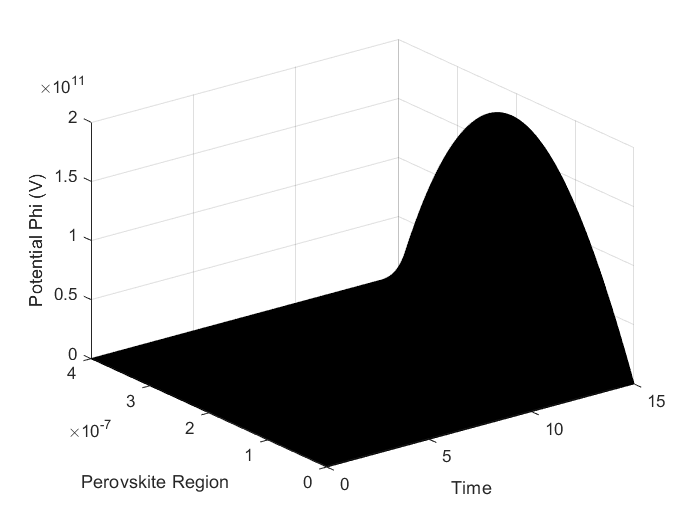

% Not very intuitive as to how we ended up with such forms of
% the curves - maybe because light or voltage profiles need fixing, maybe because we need to implement 
% Neumann Boundary Condition after all. Maybe its because we have not implemented the full solar cell
% (as said in the beginning - only one of 3 layers) just its semiconductor absorber region yet.
figure; surf(t,x,phixt);
xlabel("Time"); ylabel("Perovskite Region"); zlabel("Potential Phi (V)");

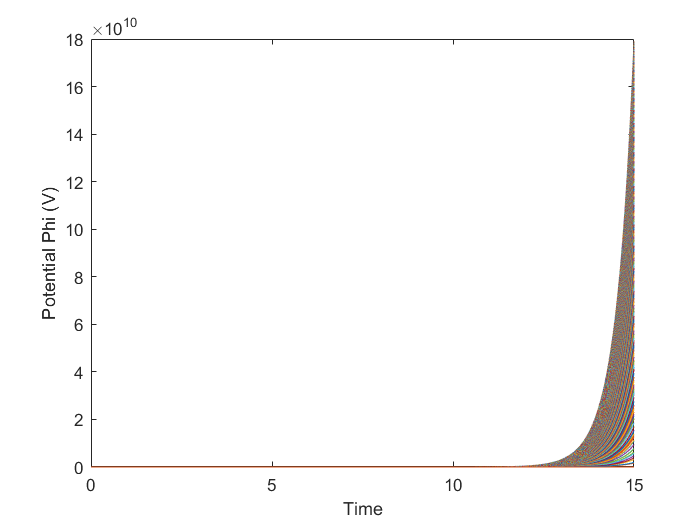

plot(t,phixt); xlabel("Time"); ylabel("Potential Phi (V)");

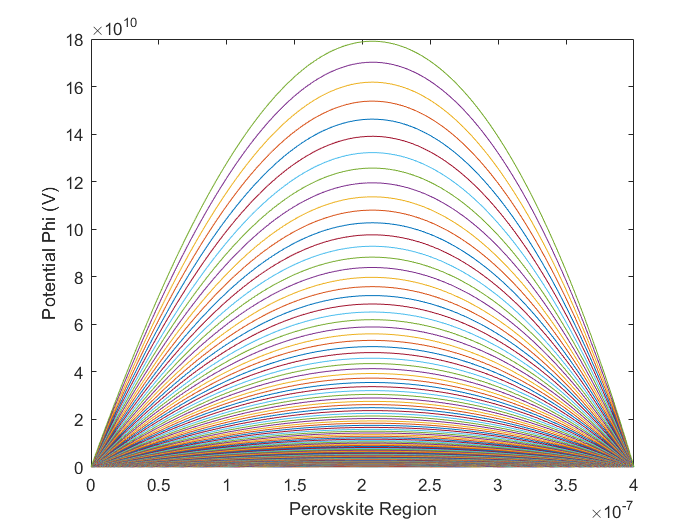

plot(x,phixt); xlabel("Perovskite Region"); ylabel("Potential Phi (V)");

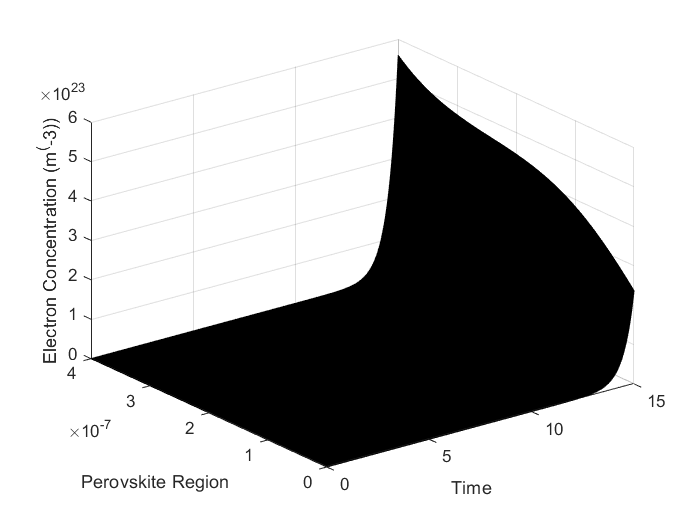

figure; surf(t,x,nxt);
xlabel("Time"); ylabel("Perovskite Region"); zlabel("Electron Concentration (m^(-3))");

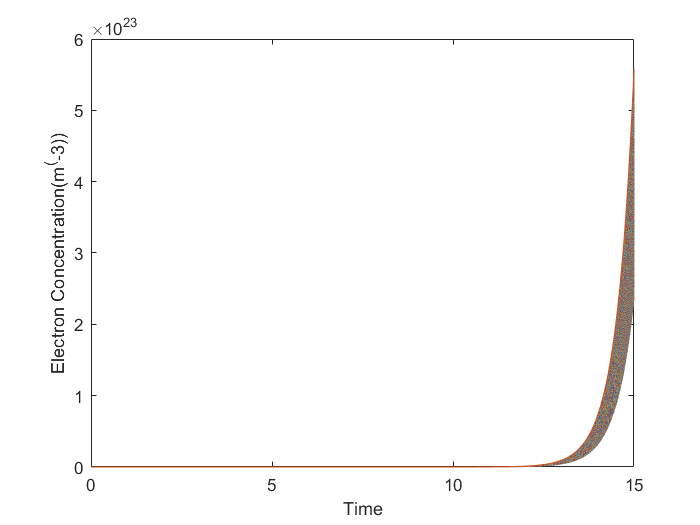

plot(t,nxt); xlabel("Time"); ylabel("Electron Concentration(m^(-3))");

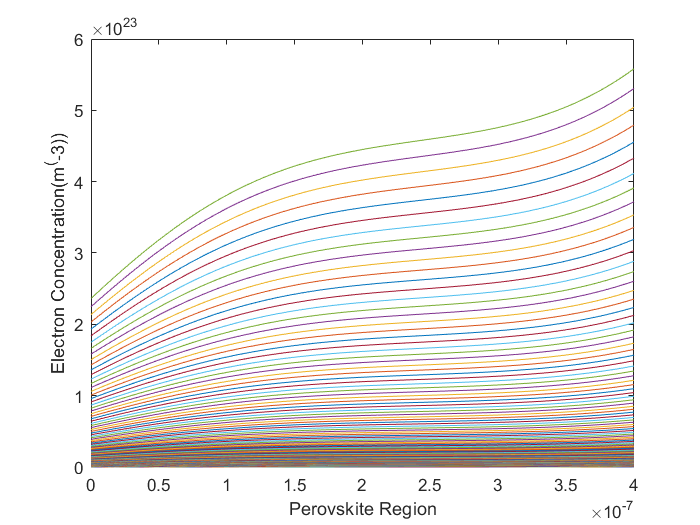

plot(x,nxt); xlabel("Perovskite Region"); ylabel("Electron Concentration(m^(-3))");

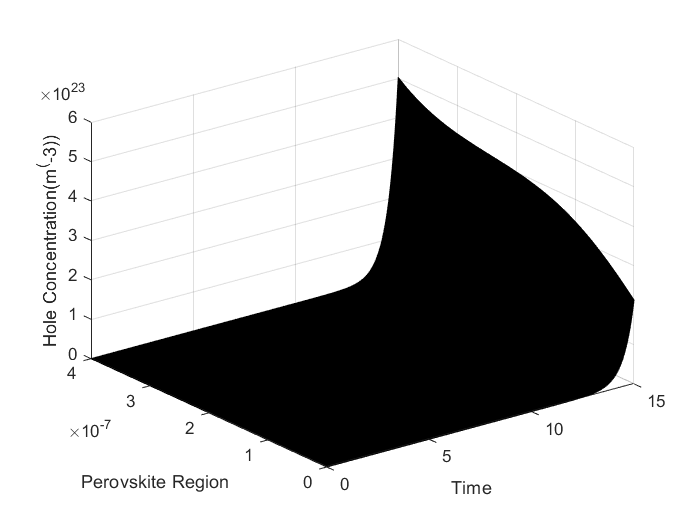

figure; surf(t,x,pxt);
xlabel("Time"); ylabel("Perovskite Region"); zlabel("Hole Concentration(m^(-3))");

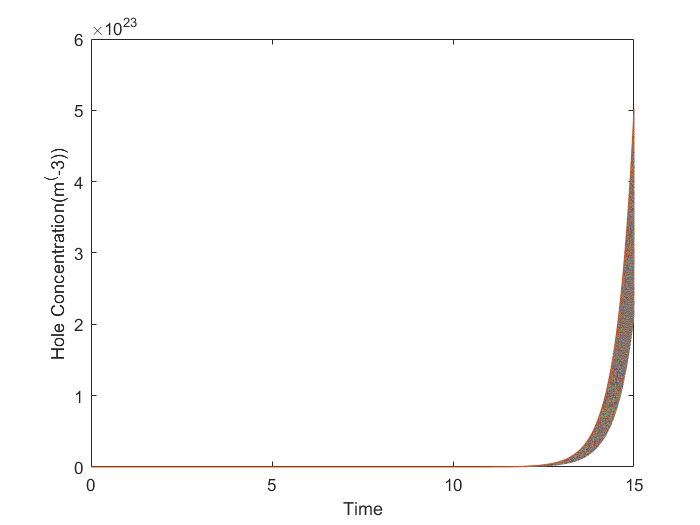

plot(t,pxt); xlabel("Time"); ylabel("Hole Concentration(m^(-3))");

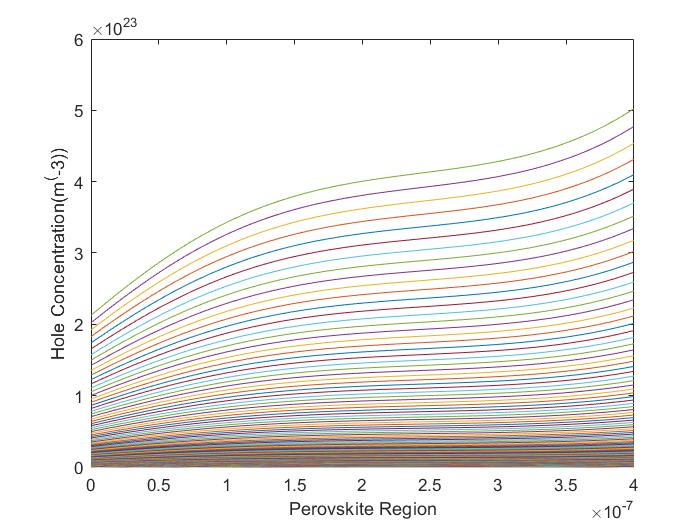

plot(x,pxt); xlabel("Perovskite Region"); ylabel("Hole Concentration(m^(-3))");

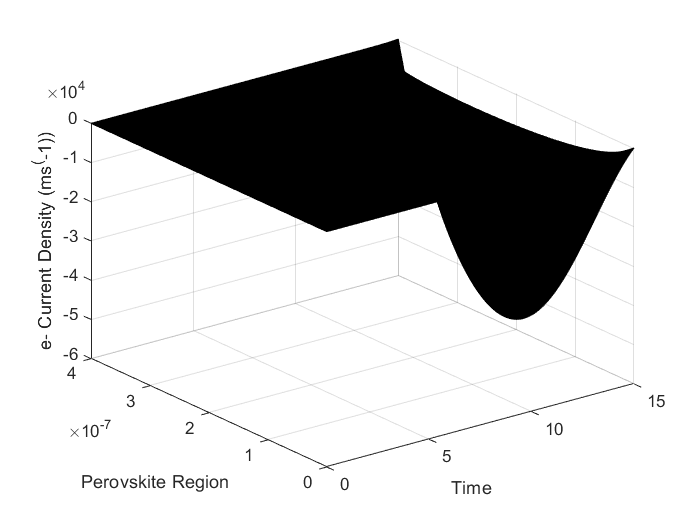

figure; surf(t,x,Jnxt);
xlabel("Time"); ylabel("Perovskite Region"); zlabel("e- Current Density (ms^(-1))");

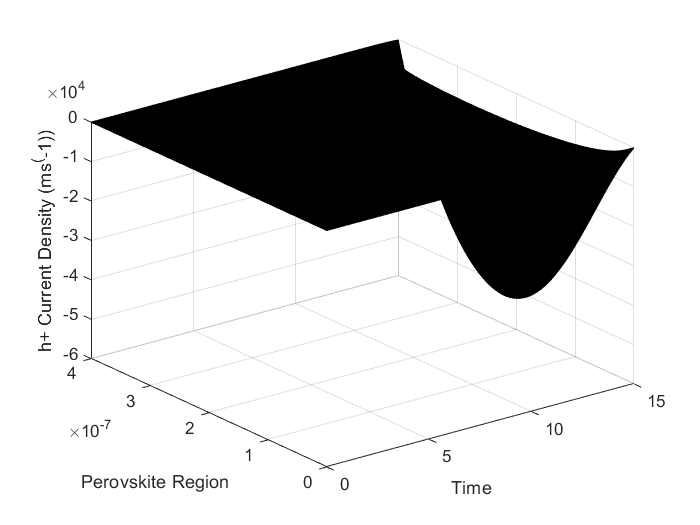

surf(t,x,Jpxt);
xlabel("Time"); ylabel("Perovskite Region"); zlabel("h+ Current Density (ms^(-1))");

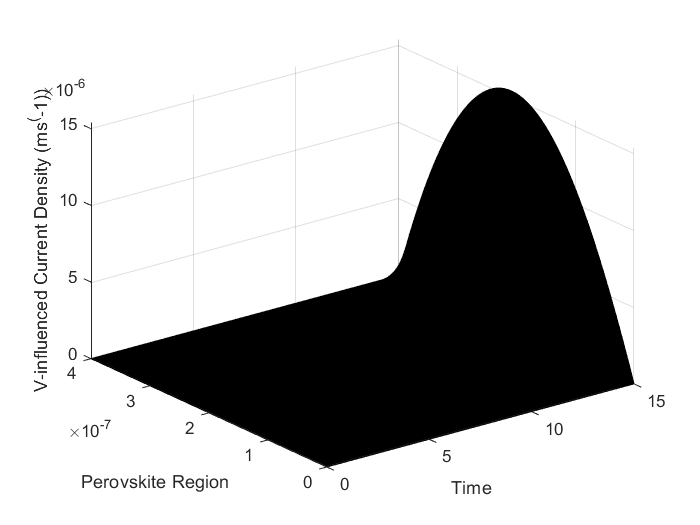

surf(t,x,Jphixt);
xlabel("Time"); ylabel("Perovskite Region"); zlabel("V-influenced Current Density (ms^(-1))");

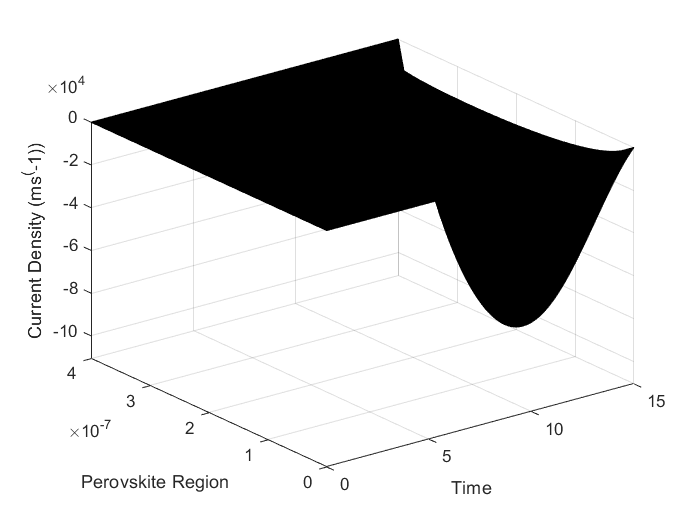

figure; surf(t,x,Jxt);
xlabel("Time"); ylabel("Perovskite Region"); zlabel("Current Density (ms^(-1))");

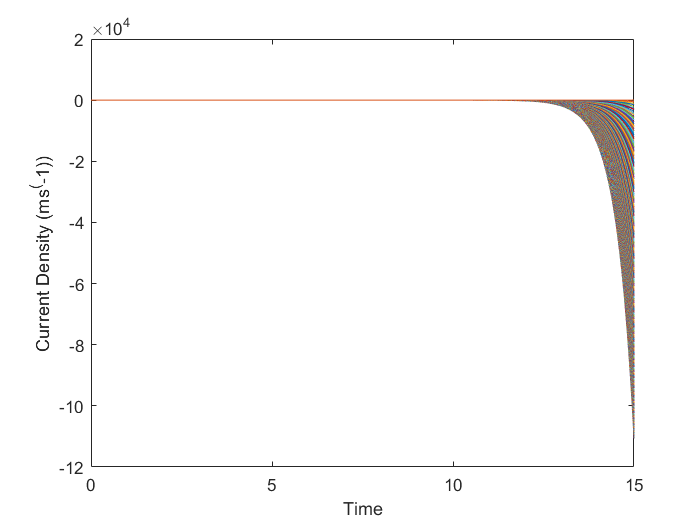

plot(t,Jxt); xlabel("Time"); ylabel("Current Density (ms^(-1))");

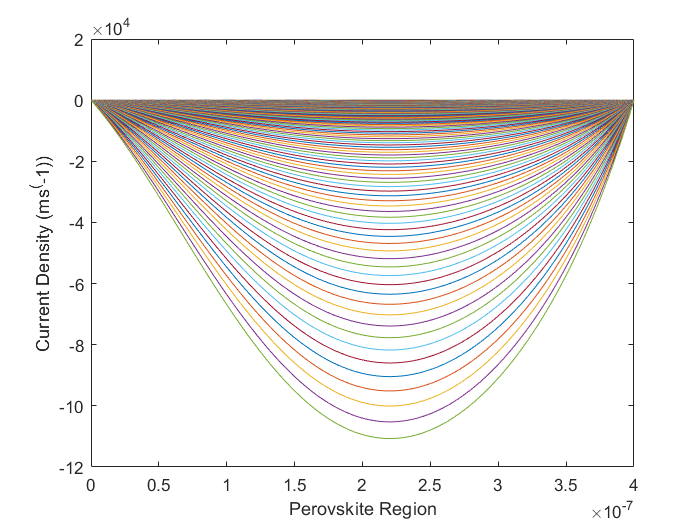

plot(x,Jxt); xlabel("Perovskite Region"); ylabel("Current Density (ms^(-1))");

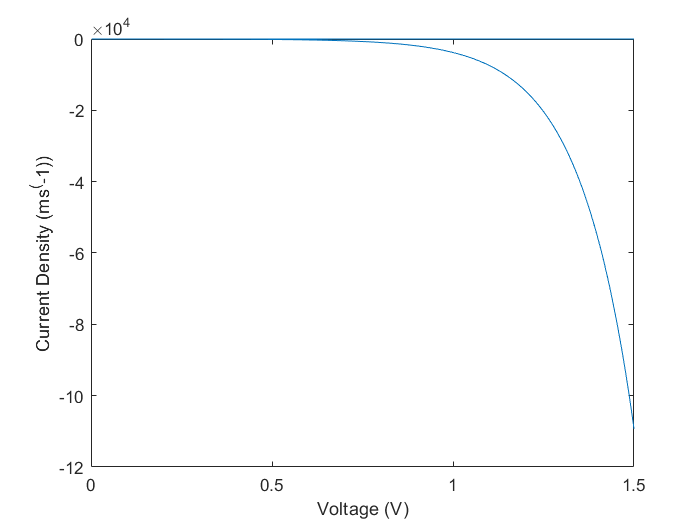

plot(V,Jxt(200,:)); xlabel("Voltage (V)"); ylabel("Current Density (ms^(-1))");

% At least the J-V curve looks like it has the correct trends, I think some
% modification in the current density relations should be enough to set its values right as well.